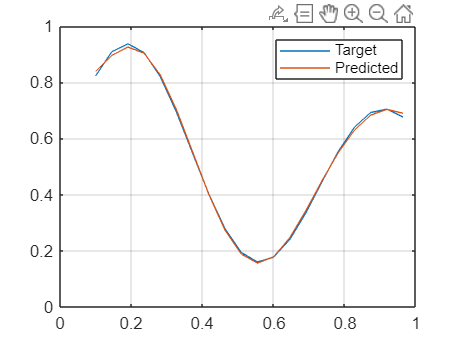

clear all
clc
%įėjimai nuo 0,1 iki 1 (22 taškai)
x = 0.1:1/22:1;
y = (1 + 0.6*sin(2*pi*x/0.7) + 0.3*sin(2*pi*x)) / 2;
figure(1)
plot(x, y);
grid on

% Pirmas sluoksnis (6 perceptronai)
w11_1 = randn(1);
w21_1 = randn(1);
w31_1 = randn(1);
w41_1 = randn(1);
w51_1 = randn(1);
w61_1 = randn(1);
b1_1 = randn(1);
b2_1 = randn(1);
b3_1 = randn(1);
b4_1 = randn(1);
b5_1 = randn(1);
b6_1 = randn(1);

% Antras sluoksnis
w11_2 = randn(1);
w12_2 = randn(1);
w13_2 = randn(1);
w14_2 = randn(1);
w15_2 = randn(1);
w16_2 = randn(1);
b1_2 = randn(1);

% Tušti vektoriai klaidoms ir išėjimams
e = zeros(20, 1);
eta = 0.1;
Y = zeros(1, length(x));

% Treniravimo procesas
for n = 1:25000         % epochų skaičius
    for i = 1:length(x)
       

        % Pirmo sluoksnio neuronų aktyvacijos 
        v1_1 = x(i)*w11_1 + b1_1;
        v2_1 = x(i)*w21_1 + b2_1;
        v3_1 = x(i)*w31_1 + b3_1;
        v4_1 = x(i)*w41_1 + b4_1;
        v5_1 = x(i)*w51_1 + b5_1;
        v6_1 = x(i)*w61_1 + b6_1;
        
        % aktyvacijos funkcija (hiperbolinio tangento išvestinė)
        y1_1 = tanh(v1_1);
        y2_1 = tanh(v2_1);
        y3_1 = tanh(v3_1);
        y4_1 = tanh(v4_1);
        y5_1 = tanh(v5_1);
        y6_1 = tanh(v6_1);
        
        % antras sluoksnis
        % pasvertos sumos
        v1_2 = y1_1*w11_2 + y2_1*w12_2 + y3_1*w13_2 + y4_1*w14_2 + y5_1*w15_2 + y6_1*w16_2 + b1_2;
        y1_2 = v1_2;
        Y(i) = y1_2;
        
        % klaidos skaičiavimas
        % error nusako kaip nutoles apskaiciuotas atsakymas nuo tikrojo
        e = y(i) - y1_2;
        
        % išėjimo klaida
        delta1_2 = e;
        
        % paslepto sluoksnio klaidos gradiento skaičiavimas
        delta1_1 = (1 - tanh(v1_1)^2) * delta1_2 * w11_2;
        delta2_1 = (1 - tanh(v2_1)^2) * delta1_2 * w12_2;
        delta3_1 = (1 - tanh(v3_1)^2) * delta1_2 * w13_2;
        delta4_1 = (1 - tanh(v4_1)^2) * delta1_2 * w14_2;
        delta5_1 = (1 - tanh(v5_1)^2) * delta1_2 * w15_2;
        delta6_1 = (1 - tanh(v6_1)^2) * delta1_2 * w16_2;
        
        % atnaujinti duomenis antrame sluoksnyje
        w11_2 = w11_2 + eta * delta1_2 * y1_1;
        w12_2 = w12_2 + eta * delta1_2 * y2_1;
        w13_2 = w13_2 + eta * delta1_2 * y3_1;
        w14_2 = w14_2 + eta * delta1_2 * y4_1;
        w15_2 = w15_2 + eta * delta1_2 * y5_1;
        w16_2 = w16_2 + eta * delta1_2 * y6_1;
        b1_2 = b1_2 + eta * delta1_2;
        
        % atnaujinti svoriai antram sluoksnyje
        w11_1 = w11_1 + eta * delta1_1 * x(i);
        w21_1 = w21_1 + eta * delta2_1 * x(i);
        w31_1 = w31_1 + eta * delta3_1 * x(i);
        w41_1 = w41_1 + eta * delta4_1 * x(i);
        w51_1 = w51_1 + eta * delta5_1 * x(i);
        w61_1 = w61_1 + eta * delta6_1 * x(i);
        
        b1_1 = b1_1 + eta * delta1_1;
        b2_1 = b2_1 + eta * delta2_1;
        b3_1 = b3_1 + eta * delta3_1;
        b4_1 = b4_1 + eta * delta4_1;
        b5_1 = b5_1 + eta * delta5_1;
        b6_1 = b6_1 + eta * delta6_1;
    end
end

hold on
plot(x, Y)
hold off
legend('Target', 'Predicted')


% nera testavimo